- Plot the exponential function between *x* = -10 and 10 using a red dashed line, then plot the points at each integer value of *x* in large green crosses. Remember to add axes labels and a figure title.

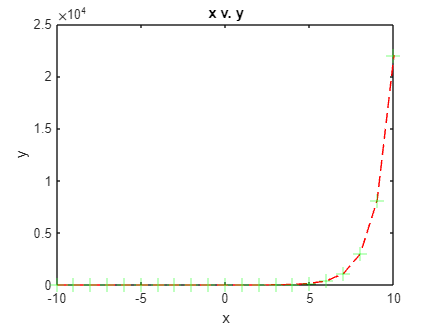

x = -10:10;
y = exp(x);


% Plot the exponential function as a red dashed line
plot(x, y, 'r--')

%plot on the same graph
hold on

% Plot the points at each integer value of x in large green crosses
plot(x, y, 'g+', 'MarkerSize', 10);

xlabel('x')
ylabel('y')
title('x v. y')

2. Use 2 subplots above and below each other to plot both sin(*x*) and cos(*x*) between -2π and 2π. Customise the plots any way you like.

%x = -2*pi:2*pi;
%linspace make the graph smoother, 100 equally spaced values
x = linspace(-2*pi, 2*pi, 100);

%set y value of each graph
y = sin(x)

y =     0.0000    0.1266    0.2511    0.3717    0.4862    0.5929    0.6901    0.7761    0.8497    0.9096    0.9549    0.9848    0.9989    0.9969    0.9788    0.9450    0.8960    0.8326    0.7557    0.6668    0.5671    0.4582    0.3420    0.2203    0.0951   -0.0317   -0.1580   -0.2817   -0.4009   -0.5137   -0.6182   -0.7127   -0.7958   -0.8660   -0.9224   -0.9638   -0.9898   -0.9999   -0.9938   -0.9718   -0.9341   -0.8815   -0.8146   -0.7346   -0.6428   -0.5406   -0.4298   -0.3120   -0.1893   -0.0634


y1 = cos(x)

y1 =     1.0000    0.9920    0.9679    0.9284    0.8738    0.8053    0.7237    0.6306    0.5272    0.4154    0.2969    0.1736    0.0476   -0.0792   -0.2048   -0.3271   -0.4441   -0.5539   -0.6549   -0.7453   -0.8237   -0.8888   -0.9397   -0.9754   -0.9955   -0.9995   -0.9874   -0.9595   -0.9161   -0.8580   -0.7861   -0.7015   -0.6056   -0.5000   -0.3863   -0.2665   -0.1423   -0.0159    0.1108    0.2358    0.3569    0.4723    0.5801    0.6785    0.7660    0.8413    0.9029    0.9501    0.9819    0.9980


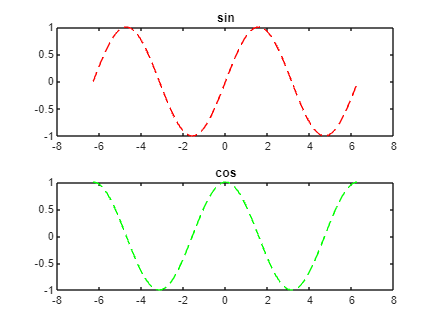


%2 row, 1 coloumn, index 1
subplot(2, 1, 1)
plot(x, y, 'r--')
title('sin')

%2 row, 1 coloumn, index 2
subplot(2, 1, 2)
plot(x, y1, 'g--')
title('cos')

3. Plot the following data in a pie chart and explode the Honda and Mercedes segments.

figure;
carData = [37210, 412178, 366040, 53442, 157803, 210000, 845213]

carData =        37210      412178      366040       53442      157803      210000      845213


carBrands = {'BMW', 'Honda', 'Isuzu', 'Mercedes', 'Mitsubishi', 'Nissan', 'Toyota'}

carBrands = 1×7 cell array
    {'BMW'}    {'Honda'}    {'Isuzu'}    {'Mercedes'}    {'Mitsubishi'}    {'Nissan'}    {'Toyota'}


explode = [0, 1, 0, 1, 0, 0, 0]

explode =      0     1     0     1     0     0     0


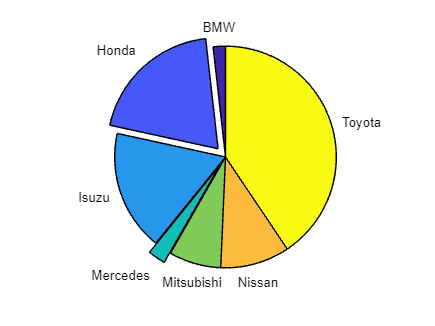

pie(carData, explode, carBrands)

4. Plot... between -10 and 10, but only display the *y*-axis between 0 and 1.

x = linspace(-10, 10, 100);
y = 1./(x-1).^2

y =     0.0083    0.0086    0.0089    0.0093    0.0096    0.0100    0.0104    0.0109    0.0114    0.0119    0.0124    0.0130    0.0136    0.0143    0.0150    0.0157    0.0166    0.0175    0.0184    0.0195    0.0206    0.0219    0.0233    0.0248    0.0264    0.0283    0.0303    0.0325    0.0350    0.0378    0.0410    0.0446    0.0486    0.0533    0.0586    0.0648    0.0720    0.0805    0.0905    0.1026    0.1173    0.1354    0.1581    0.1869    0.2244    0.2744    0.3432    0.4415    0.5890    0.8249


ylim = [0,1]

ylim =      0     1


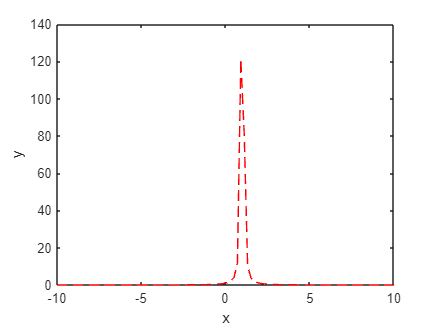


figure;
plot(x, y, 'r--')
xlabel('x')
ylabel('y')

15. Write a while loop that multiplies a number by 2 until the answer is greater than 100. Test your code with numbers of your choice.

%N = input("Enter Number")
%while N * 2 < 100
%    N = N * 2
%end
%disp(N)

16. Write a function that accepts a number as an argument. Check if it is positive or negative. If it is positive then double it, if it is negative then halve it. Return the value. Remember to give your function a descriptive name.

     1     1     2     3     5     8    13    21    34



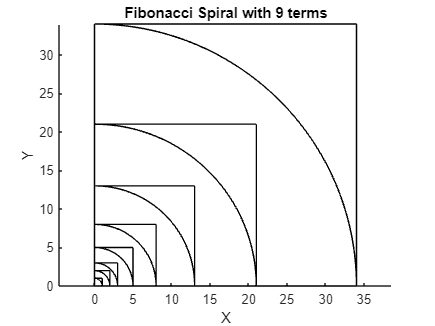

%numcheck(-4)
%numbers(2, 7, 1)
%printVec()
%find1()
%matZero(0, randi([-5, 5], 3, 3))
%tolSeries(0.0005)
%eulerFac(7)
fiboPlot(9)

function numEnd = numcheck(N)
    is = isnumeric(N);
    if is == 1
        if N >= 0
            numEnd = N * 2;
        else
            numEnd = N/2;
            numEnd = abs(numEnd);
        end
    else
        disp("Nice try")
    end
    return
end

21. Write a function that accepts 3 numbers as arguments. Add the largest 2 numbers together. Return the result.

function sumlarge = numbers(num1, num2, num3)
    numbers = [num1, num2, num3];
    sortednum = sort(numbers, 'descend');
    sumlarge = sortednum(1) + sortednum(2);
return
end

23. Write a function that accepts a vector as an input argument. The function should print the number of elements of the input vector as well as its smallest 2 values. If the vector has less than 2 elements the function should tell the user it requires more inputs.

function printVec()
    vNum = input('Number of your elements');
    vIn = [];

    for j = 1:vNum
        value = input("Enter a value");
        vIn = [vIn, value];
    end
    if numel(vIn) < 2
        disp("Require more input")
    else
        sorted = sort(vIn, "ascend");
        fprintf("Number of elements : %d\n", vNum)
        fprintf("Smallest 2 : %d, \n%d", sorted(1), sorted(2))
    end
end

24. Write a script that creates a random vector of 1’s and 0’s then finds the indexes of the non-zero elements (read about the find function).

function find1()
    vec = randi([0, 1], 1, 5);
    disp(vec)
    ind = find(vec);
    disp(ind)
end

28. Create a function which takes a value, *x*, and matrix, ***A***, as inputs. It will set any entries of the input matrix greater than *x* equal to 0 and return the result.

function modifiedMat = matZero(x, A)
    disp("Matrix Input : ")
    disp(A)
    larger = A > x;
    A(larger) = 0;
    modifiedMat = A;
    return
end

29. The following series converges to 1. Write a function that accepts a number specifying a tolerance, *tol*, as input argument. Calculate the sum of the series, until the answer is within *tol* away from 1. Display how many terms are required for the given precision.

function tolSeries(tol)
    s = 0;
    n = 1;
    while s <= 1 - tol
        s = s + 1/(2^n);
        n = n + 1;
    end
    disp(s)
    disp(n-1)
end

30. Write a function which accepts a number, n, as input argument. Calculate Euler’s number up to and including n terms using the following recursive formula. e = sum_{i=0}^{n} 1/i!

function eulerFac(n)
    e = 0;
    for j = 0:n
        e = e + 1/factorial(j);
    end
    disp(e)
end

**Challenge Problem**

The golden spiral can be approximated using the Fibonacci sequence:        

                                       1, 1, 2, 3, 5, 8, 13, 21, 34…

where each number is the sum of the previous 2 numbers.

Recreate the Fibonacci spiral shown on the next page by plotting squares as shown with lengths equal to the numbers in the Fibonacci sequence, and then adding quarter circular arcs, which join opposite corners of each square, to the plot. The file should be a function or script that specifies the number of terms in the Fibonacci sequence and produces the corresponding plot.

**Hint:** You will probably need to use pen and paper to figure out the coordinates of each of the squares. Also to plot a square you must use 5 points. The first and last coordinate points must be the same!

function fiboPlot(n)
    seq = zeros(1, n);      %create vector n indices value 0
    seq(1) = 1;
    seq(2) = 1;
    for j = 3:n
        seq(j) = seq(j-1) + seq(j-2);
    end
    disp(seq)

    % Plot the Fibonacci spiral
    figure;
    hold on;
    for i = 1:n
        rectangle('Position', [0 0 seq(i) seq(i)], 'EdgeColor', 'k');
        axis equal;
        if i > 1
            r = seq(i);
            theta = 0:0.01:pi/2;
            x = r * cos(theta);
            y = r * sin(theta);
            plot(x, y, 'k');
        end
        pause(0.2);  % Pause to visualize the drawing step by step
    end
    
    title(['Fibonacci Spiral with ', num2str(n), ' terms']);
    xlabel('X');
    ylabel('Y');
end